# IC - 10.23.25 Linear Regression

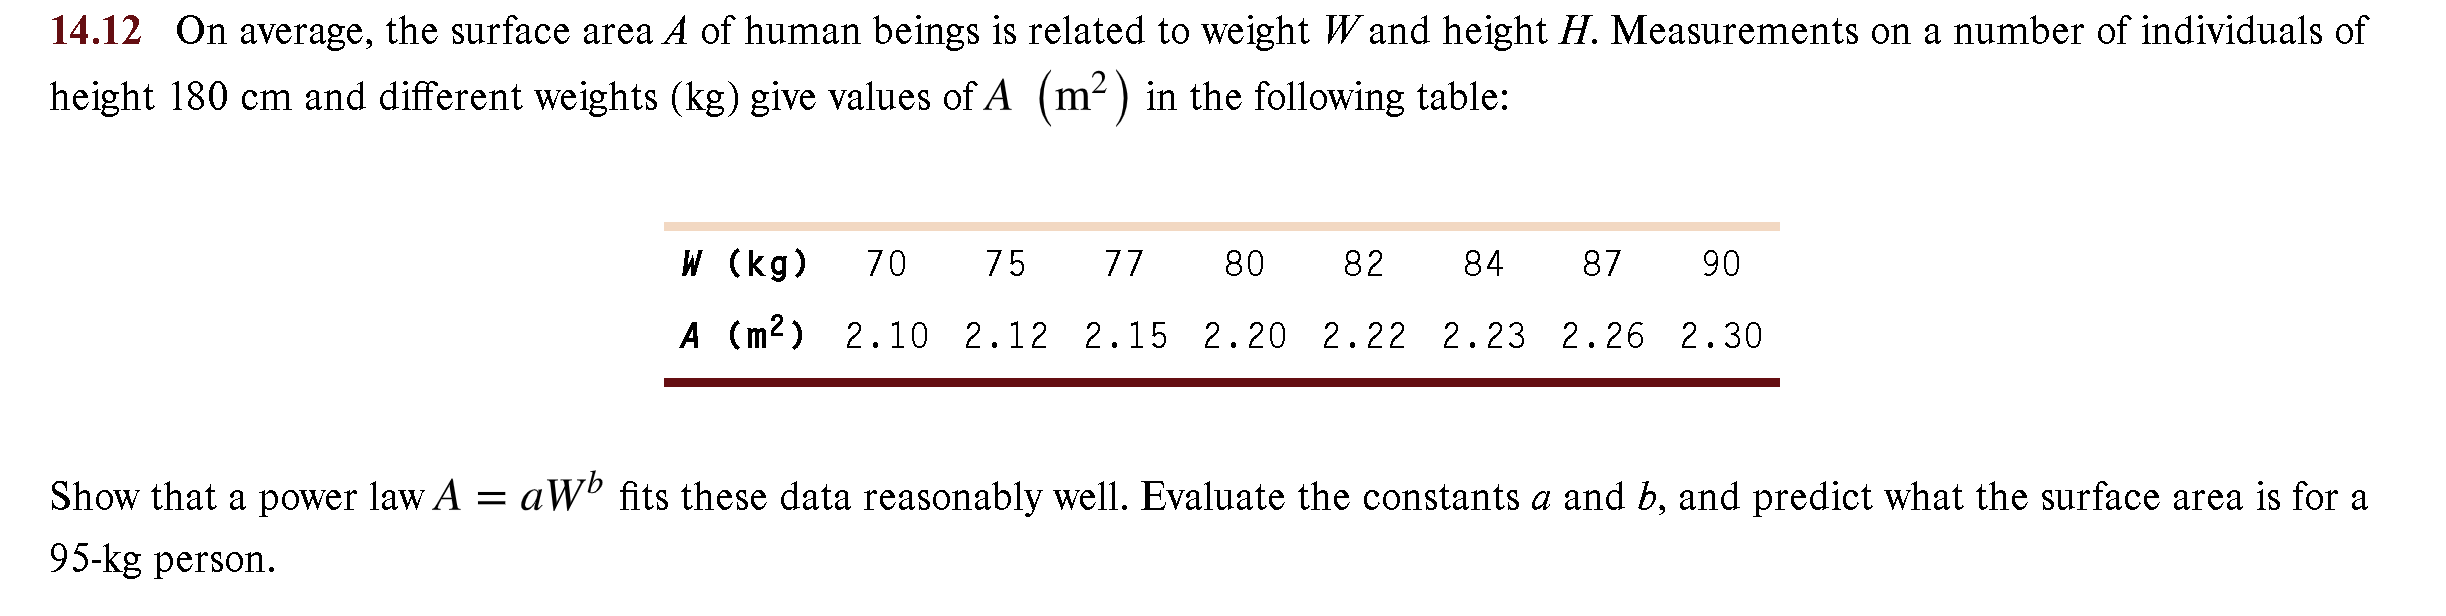

On average, the surface area A of human beings is related to weight W and height H. Measurements on a number of individuals of height 180 cm and different weights (kg) give values of A (m2) in the following table.

Show that a power law A = alph*W^b fits these data reasonably well. Evaluate the constants alph and b, and predict the surface area is for a 95 kg person.

clear; clc; clf;
W = [70, 75, 77, 80, 82, 84, 87, 90]; % (kg)
A = [2.10, 2.12, 2.15, 2.20, 2.22, 2.23, 2.26, 2.30]; % (m^2)
% A = f(W) for h = 180
help linregr

  linregr: linear regression curve fitting
  [a, r2] = linregr(x,y): Least squares fit of straight
  line to data by solving the normal equations
  input:
  x = independent variable
  y = dependent variable
  output:
  a = vector of slope, a(1), and intercept, a(2)
  r2 = coefficient of determination



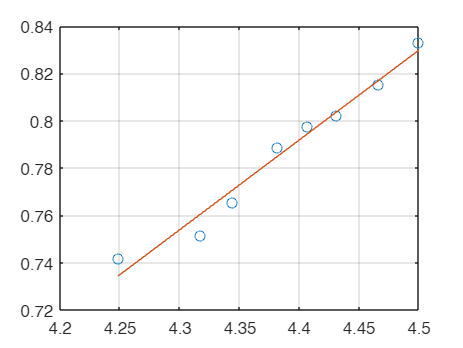

a =     0.3799   -0.8797


r2 = 0.9711

% [a, r2] = linregr(W,A) % linear isn't the best fit

% Linearize
% log10(y) = log10(alph) + b*log10(x)
[a, r2] = linregr(log(W),log(A))

alph = exp(a(2));
b = a(1)

b = 0.3799

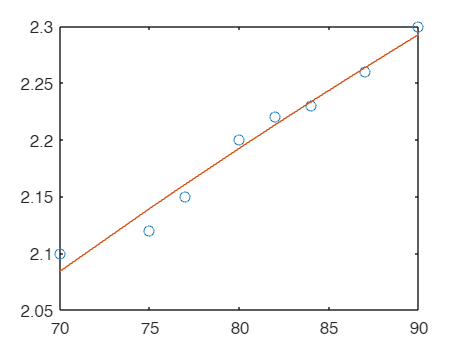


% plot W,A
figure;
plot(W,A,'o');
hold on;
plot(W, alph.*W.^b)
hold off;


% Calculate for a person of W = 95 kg
W95 = 95;
A95 = alph.*W95.^b % m^2

A95 = 2.3404